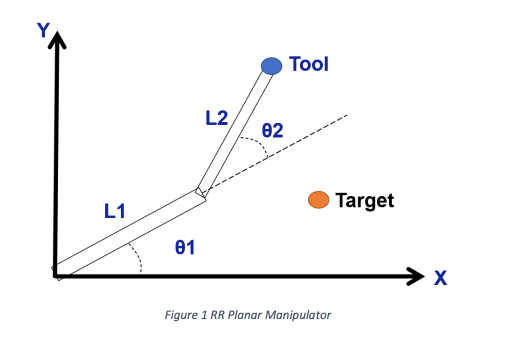

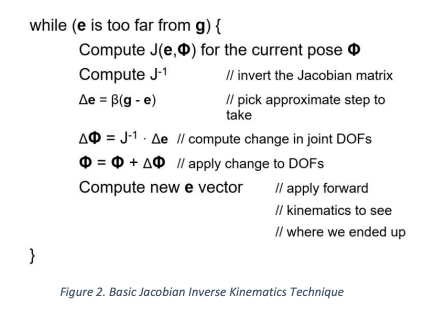

%Robot joints' lengths
L1 = 1; %m
L2 = 2;

%Defining our tooltip's goal, in this case its (2,2)
gx = 2;
gy = 2;
g = [gx;gy];

%Initialize some position the robot has in the beginning
theta1 = pi/2;
theta2 = pi/2;
theta = [theta1;theta2]

theta =     1.5708
    1.5708



%Size of step
beta = 0.2;

%Initialize delta_e to something
delta_e = [Inf;Inf]; 

%Iterator to keep count of iterations 
iter = 0

iter = 0


%For task 2 plotting
iters = [];
errors = [];

%When delta_e is small enough, the robot arm has reached its goal. 
%This ought to be close enough.
while or(abs(delta_e(1,1)) > 0.00001, abs(delta_e(2))>0.00001)
    
    %Derivations of arm's joints' differential equations
    j11 = -L1*sin(theta1)-L2*sin(theta1+theta2);
    j12 = -L2*sin(theta1+theta2);
    j21 = L1*cos(theta1)+L2*cos(theta1+theta2);
    j22 = L2*cos(theta1+theta2);
    %Jacobian matrix
    jacobian = [j11, j12; j21, j22];
    inv_jacobian = inv(jacobian);
    
    %Tool tip's coordinates
    ex = L1*cos(theta(1,1))+L2*cos(theta(1,1) + theta(2,1));
    ey = L1*sin(theta(1,1))+L2*sin(theta(1,1)+theta(2,1));
    e = [ex;ey];
    
    delta_e = beta*(g-e);
    delta_theta = inv_jacobian\delta_e;
    theta = theta + delta_theta;
    iter = iter+1
    
    %For plotting
    error = abs(sqrt((ex-gx).^2+(ey-gy).^2));
    iters(end+1) = iter
    errors(end+1) = error
end

iter = 1

iters = 1

errors = 4.1231

iter = 2

iters =      1     2


errors =     4.1231    0.8736


iter = 3

iters =      1     2     3


errors =     4.1231    0.8736    0.5566


iter = 4

iters =      1     2     3     4


errors =     4.1231    0.8736    0.5566    0.2665


iter = 5

iters =      1     2     3     4     5


errors =     4.1231    0.8736    0.5566    0.2665    0.1318


iter = 6

iters =      1     2     3     4     5     6


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537


iter = 7

iters =      1     2     3     4     5     6     7


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654


iter = 8

iters =      1     2     3     4     5     6     7     8


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341


iter = 9

iters =      1     2     3     4     5     6     7     8     9


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725


iter = 10

iters =      1     2     3     4     5     6     7     8     9    10


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913


iter = 11

iters =      1     2     3     4     5     6     7     8     9    10    11


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965


iter = 12

iters =      1     2     3     4     5     6     7     8     9    10    11    12


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912


iter = 13

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770


iter = 14

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556


iter = 15

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284


iter = 16

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970


iter = 17

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970    0.3629


iter = 18

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970    0.3629    0.3273


iter = 19

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970    0.3629    0.3273    0.2914


iter = 20

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970    0.3629    0.3273    0.2914    0.2563


iter = 21

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970    0.3629    0.3273    0.2914    0.2563    0.2228


iter = 22

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970    0.3629    0.3273    0.2914    0.2563    0.2228    0.1913


iter = 23

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970    0.3629    0.3273    0.2914    0.2563    0.2228    0.1913    0.1625


iter = 24

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970    0.3629    0.3273    0.2914    0.2563    0.2228    0.1913    0.1625    0.1365


iter = 25

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970    0.3629    0.3273    0.2914    0.2563    0.2228    0.1913    0.1625    0.1365    0.1134


iter = 26

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970    0.3629    0.3273    0.2914    0.2563    0.2228    0.1913    0.1625    0.1365    0.1134    0.0932


iter = 27

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970    0.3629    0.3273    0.2914    0.2563    0.2228    0.1913    0.1625    0.1365    0.1134    0.0932    0.0759


iter = 28

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970    0.3629    0.3273    0.2914    0.2563    0.2228    0.1913    0.1625    0.1365    0.1134    0.0932    0.0759    0.0612


iter = 29

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970    0.3629    0.3273    0.2914    0.2563    0.2228    0.1913    0.1625    0.1365    0.1134    0.0932    0.0759    0.0612    0.0489


iter = 30

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970    0.3629    0.3273    0.2914    0.2563    0.2228    0.1913    0.1625    0.1365    0.1134    0.0932    0.0759    0.0612    0.0489    0.0387


iter = 31

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970    0.3629    0.3273    0.2914    0.2563    0.2228    0.1913    0.1625    0.1365    0.1134    0.0932    0.0759    0.0612    0.0489    0.0387


iter = 32

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970    0.3629    0.3273    0.2914    0.2563    0.2228    0.1913    0.1625    0.1365    0.1134    0.0932    0.0759    0.0612    0.0489    0.0387


iter = 33

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970    0.3629    0.3273    0.2914    0.2563    0.2228    0.1913    0.1625    0.1365    0.1134    0.0932    0.0759    0.0612    0.0489    0.0387


iter = 34

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970    0.3629    0.3273    0.2914    0.2563    0.2228    0.1913    0.1625    0.1365    0.1134    0.0932    0.0759    0.0612    0.0489    0.0387


iter = 35

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970    0.3629    0.3273    0.2914    0.2563    0.2228    0.1913    0.1625    0.1365    0.1134    0.0932    0.0759    0.0612    0.0489    0.0387


iter = 36

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970    0.3629    0.3273    0.2914    0.2563    0.2228    0.1913    0.1625    0.1365    0.1134    0.0932    0.0759    0.0612    0.0489    0.0387


iter = 37

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970    0.3629    0.3273    0.2914    0.2563    0.2228    0.1913    0.1625    0.1365    0.1134    0.0932    0.0759    0.0612    0.0489    0.0387


iter = 38

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970    0.3629    0.3273    0.2914    0.2563    0.2228    0.1913    0.1625    0.1365    0.1134    0.0932    0.0759    0.0612    0.0489    0.0387


iter = 39

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970    0.3629    0.3273    0.2914    0.2563    0.2228    0.1913    0.1625    0.1365    0.1134    0.0932    0.0759    0.0612    0.0489    0.0387


iter = 40

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970    0.3629    0.3273    0.2914    0.2563    0.2228    0.1913    0.1625    0.1365    0.1134    0.0932    0.0759    0.0612    0.0489    0.0387


iter = 41

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970    0.3629    0.3273    0.2914    0.2563    0.2228    0.1913    0.1625    0.1365    0.1134    0.0932    0.0759    0.0612    0.0489    0.0387


iter = 42

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970    0.3629    0.3273    0.2914    0.2563    0.2228    0.1913    0.1625    0.1365    0.1134    0.0932    0.0759    0.0612    0.0489    0.0387


iter = 43

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970    0.3629    0.3273    0.2914    0.2563    0.2228    0.1913    0.1625    0.1365    0.1134    0.0932    0.0759    0.0612    0.0489    0.0387


iter = 44

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970    0.3629    0.3273    0.2914    0.2563    0.2228    0.1913    0.1625    0.1365    0.1134    0.0932    0.0759    0.0612    0.0489    0.0387


iter = 45

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970    0.3629    0.3273    0.2914    0.2563    0.2228    0.1913    0.1625    0.1365    0.1134    0.0932    0.0759    0.0612    0.0489    0.0387


iter = 46

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970    0.3629    0.3273    0.2914    0.2563    0.2228    0.1913    0.1625    0.1365    0.1134    0.0932    0.0759    0.0612    0.0489    0.0387


iter = 47

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970    0.3629    0.3273    0.2914    0.2563    0.2228    0.1913    0.1625    0.1365    0.1134    0.0932    0.0759    0.0612    0.0489    0.0387


iter = 48

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970    0.3629    0.3273    0.2914    0.2563    0.2228    0.1913    0.1625    0.1365    0.1134    0.0932    0.0759    0.0612    0.0489    0.0387


iter = 49

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970    0.3629    0.3273    0.2914    0.2563    0.2228    0.1913    0.1625    0.1365    0.1134    0.0932    0.0759    0.0612    0.0489    0.0387


iter = 50

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970    0.3629    0.3273    0.2914    0.2563    0.2228    0.1913    0.1625    0.1365    0.1134    0.0932    0.0759    0.0612    0.0489    0.0387


iter = 51

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970    0.3629    0.3273    0.2914    0.2563    0.2228    0.1913    0.1625    0.1365    0.1134    0.0932    0.0759    0.0612    0.0489    0.0387


iter = 52

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970    0.3629    0.3273    0.2914    0.2563    0.2228    0.1913    0.1625    0.1365    0.1134    0.0932    0.0759    0.0612    0.0489    0.0387


iter = 53

iters =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


errors =     4.1231    0.8736    0.5566    0.2665    0.1318    0.2537    0.3654    0.4341    0.4725    0.4913    0.4965    0.4912    0.4770    0.4556    0.4284    0.3970    0.3629    0.3273    0.2914    0.2563    0.2228    0.1913    0.1625    0.1365    0.1134    0.0932    0.0759    0.0612    0.0489    0.0387



%This takes 53 iterations. The size of step beta has the largest effect on
%how big this number is. Also the size of the error allowed has the ability
%trim some of the iterations away.

%TASK2

%Final angles:
theta 

theta =     0.2987
    0.7227


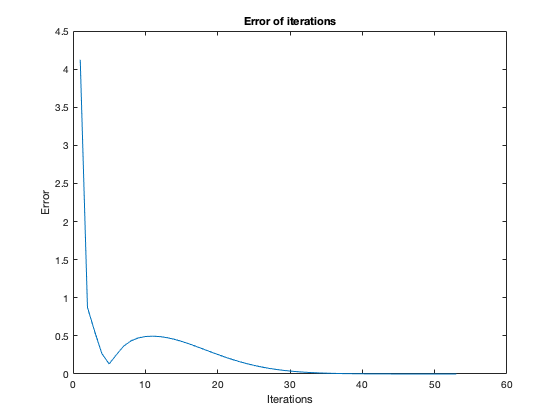


figure
plot(iters,errors)
title("Error of iterations")
xlabel("Iterations")
ylabel("Error")


%Final position of the tool tip, which maches our set goal 
e

e =     2.0000
    2.0000


%TASK3

L(1) = Link([pi/2, 0, L1, 0], 'standard');
L(2) = Link([pi/2, 0, L2, 0], 'standard');
twolink = SerialLink(L, 'name', 'two link');
T = transl(2,2,0)

T =      1     0     0     2
     0     1     0     2
     0     0     1     0
     0     0     0     1


q = twolink.ikine(T, 'mask', [1 1 0 0 0 0])

q =     0.2987    0.7227


%q matches the earlier matrix theta, so results are the same

twolink.fkine([0.2987, 0.7227])

 

ans = 
    0.5222   -0.8528         0         2
    0.8528    0.5222         0         2
         0         0         1         0
         0         0         0         1
